## [Naive Bayes](https://apmonitor.com/pds/index.php/Main/NaiveBayes)

Naive Bayes classification is a machine learning algorithm that uses Bayes' theorem to make predictions. The theorem is based on the idea that the predictors are independent of each other. In other words, the value of one predictor is not related to the value of any other predictor.

Bayes' theorem is a mathematical equation that describes the relationship between the probability of an event and the conditional probability of another event. It is typically expressed as follows:


$$P\left(A\right|B\right)=P\left(B\left|A\right)\times \frac{P\left(A\right)}{P\left(B\right)}$$


where *P(A|B)* is the conditional probability of event *A* occurring given that event *B* has already occurred, *P(B|A)* is the conditional probability of event *B* occurring given that event *A* has already occurred, *P(A)* is the probability of event *A* occurring, and *P(B)* is the probability of event *B* occurring.

In the context of Naive Bayes classification, we can use Bayes' theorem to calculate the probability that an input belongs to a particular class, given the values of the input's predictors. For example, suppose we have a dataset containing information about different types of animals. We could use Naive Bayes classification to predict the type of animal based on its color and size.

Naive Bayes algorithm is based on Bayes’ theorem with the assumption of independence between every pair of features. Naive Bayes classifiers work well in many real-world situations such as document classification and spam filtering. It works well with large and high-dimensional data sets, especially when there is at least one feature that is a strong predictor of each class.

**Advantages:** This algorithm requires a small amount of training data to estimate the necessary parameters. Naive Bayes classifiers are extremely fast compared to more sophisticated methods.

**Disadvantages:** Naive Bayes is known to be a bad estimator, but it may be the best option given the favorable training speed, low memory requirement, and fast predictions.

**Optical Character Recognition with AdaBoost**

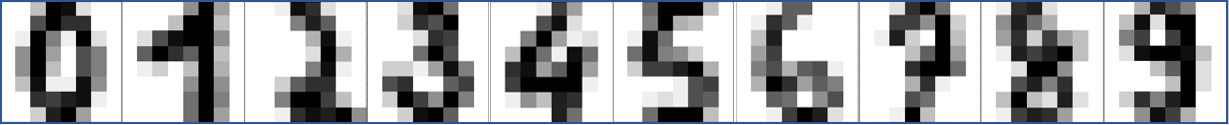

Optical character recognition (OCR) is a technology that enables the recognition of text characters in digital images. This technology can be used to automatically convert scanned documents, pictures, or other digital images that contain text into machine-readable text.

Naive Bayes is a type of machine learning algorithm that is commonly used in the field of OCR. This algorithm is based on the idea of using Bayes' theorem to make predictions about the likelihood of different outcomes based on the available data.

In the context of OCR, a Naive Bayes classifier can be trained to recognize text characters in images by learning from a large dataset of labeled images. The classifier uses Bayes' theorem to calculate the likelihood that a given image contains each of the possible text characters, and then makes a prediction about which character is most likely to be present in the image.

In this code, the GaussianNB class is used to create a Gaussian Naive Bayes classifier. The classifier is then trained on a dataset of labeled images (represented by the X and y variables) using the fit method. Finally, the classifier can be used to make predictions on new data (represented by the *X_Test* variable) programmatically with the [*predict*](https://www.mathworks.com/help/stats/linearmodel.predict.html) function. Below is a complete example with a train/test split.

### Import and Organize the Data

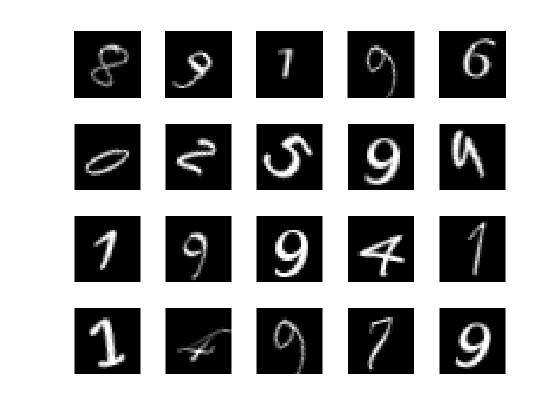

% Import dataset of numbers
digitDatasetPath = fullfile(matlabroot,'toolbox','nnet','nndemos', ...
    'nndatasets','DigitDataset');
imds = imageDatastore(digitDatasetPath, ...
    'IncludeSubfolders',true,'LabelSource','foldernames');

% Show example of dataset
figure;
perm = randperm(10000,20);
for i = 1:20
    subplot(4,5,i);
    imshow(imds.Files{perm(i)});
end

n_samples = length(imds.Files);

% Extract the images into a matrix
X_data = cell(n_samples, 1);
for i = 1:n_samples
    [X_data{i}] = deal(reshape(readimage(imds,i)',[1,28*28]));
end
X_data = cell2mat(X_data);

X_data = awgn(im2double(X_data),10,'measured');

% Save the labels of the images
Y_data = imds.Labels(1:n_samples);

% Split the data 50% training adn 50% testing
[trainInd,valInd,testInd] = dividerand(n_samples,0.5,0,0.5);

X_Train = X_data(trainInd,:);
X_Test = X_data(testInd,:);
Y_Train = Y_data(trainInd,:);
Y_Test = Y_data(testInd,:);

% Assuming X_Train is your training data, and X_Test is your test data with missing values
% Impute missing values in X_Test with the mean of the corresponding feature in X_Train
for i = 1:size(X_Test, 2)
    X_Test(isnan(X_Test(:, i)), i) = mean(X_Train(:, i), 'omitnan');
end

### Train and Evaluate the Model

% Create fit
classifier = fitcnb(array2table(X_Train),Y_Train);

% Evaluate the model performance on the test set
y_pred = predict(classifier,X_Test);
accuracy = mean(y_pred == Y_Test);
fprintf("Accuracy: %.2f\n", accuracy);

Accuracy: 0.47


### Test Individual Predictions

This is an example that shows a number from the test set and evaluates it with the Naive Bayes Classifier.

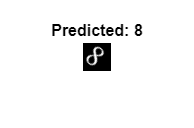

tbl = [array2table(im2double(X_Train)), array2table(Y_Train)];

% Select random nummber image
n = randi([0,n_samples],1);

% Get the prediction
reshape(readimage(imds,n)',[1,28*28]);
yp = predict(classifier,im2double(reshape(readimage(imds,n)',[1,28*28])));

% Display the image with the prediction
figure;
imshow(imds.Files{n})
titleText = "Predicted: " + string(yp);
title(titleText, 'FontSize', 12)